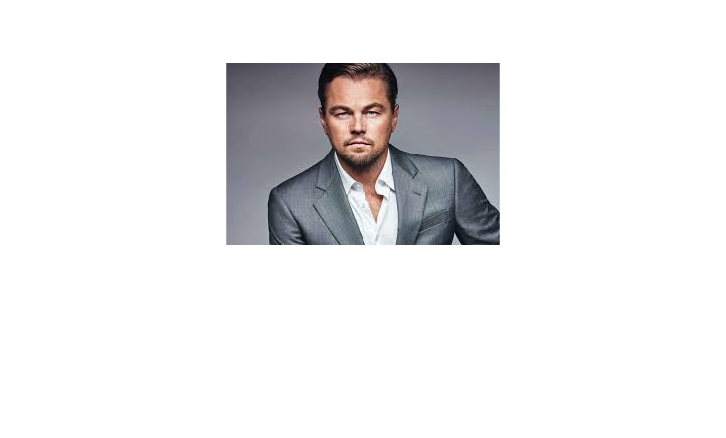

I = imread('leo.jpg');
imshow(I)

faceDetector = vision.CascadeObjectDetector('FrontalFaceCART'); % 顔検出用の学習済みカスケード検出器
faceDetector.MinSize = [210 210];
faceDetector.MaxSize = [315 315];
bboxes = step(faceDetector, I); % 顔の位置を検出
Iout = insertObjectAnnotation(I,'rectangle',bboxes,'Face'); % 枠を表示
%figure, imshow(Iout);

Iface = imcrop(I,bboxes(1,:));

Index in position 1 exceeds
array bounds.

%figure, imshow(Iface);